% Universal Constants
uconst.h = 6.62607004e-34;
uconst.hbar = uconst.h / (2*pi);
uconst.massLi6 = 9.988346e-27;

% Experimental Constants
econst.trapw = 2*pi*23.9;
econst.px = 1.44e-6;

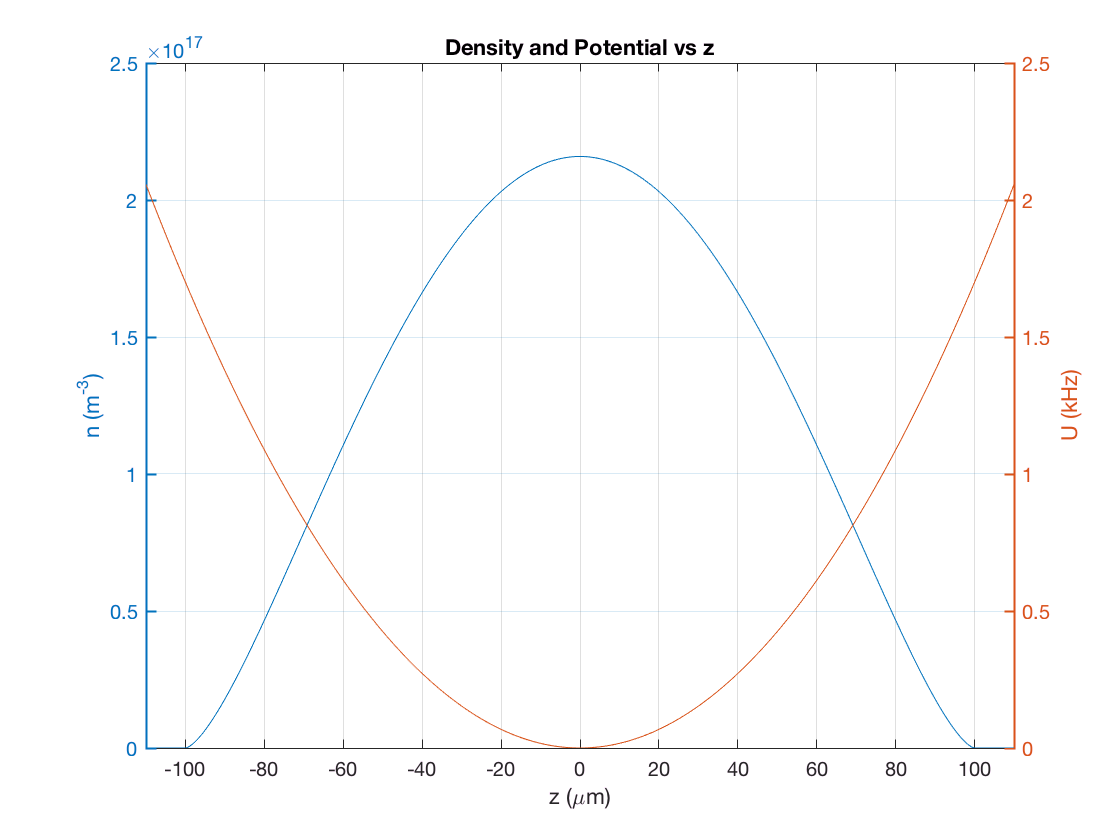

% Get n(z) as two column vectors n_z and z_i
% z_i must already have the z0 subtracted. 
n_z = [];
z_i = [];

% Fake data
R_TF = 100e-6;
xi = 0.37;
u_z = @(z) 0.5*uconst.massLi6*econst.trapw^2*z.^2;
z_i = (-1.1*R_TF:0.1e-6:1.1*R_TF)'; % 100 um TF radius
n_z = 1/(3*pi^2) * ((2*uconst.massLi6)/(uconst.hbar^2*xi))^(3/2) * (u_z(R_TF) - u_z(z_i)).^(3/2) / 2; n_z = real(n_z);
% n_z = n_z + max(n_z)/40*randn(size(n_z,1),size(n_z,2));
clearvars R_TF xi u_z

% Create potential U(z)
U_z = 0.5*uconst.massLi6*econst.trapw^2*z_i.^2;

% Create plot of n(z)
fig1 = figure; ax1 = subplot(1,1,1); grid on; title('Density and Potential vs z');  xlim([z_i(1),z_i(end)]*1e6); xlabel('z (\mum)');
yyaxis left
plot(z_i*1e6,n_z);  ylabel('n (m^{-3})');
yyaxis right
plot(z_i*1e6,U_z/(uconst.h*1e3)); ylabel('U (kHz)');

clearvars fig1 ax1

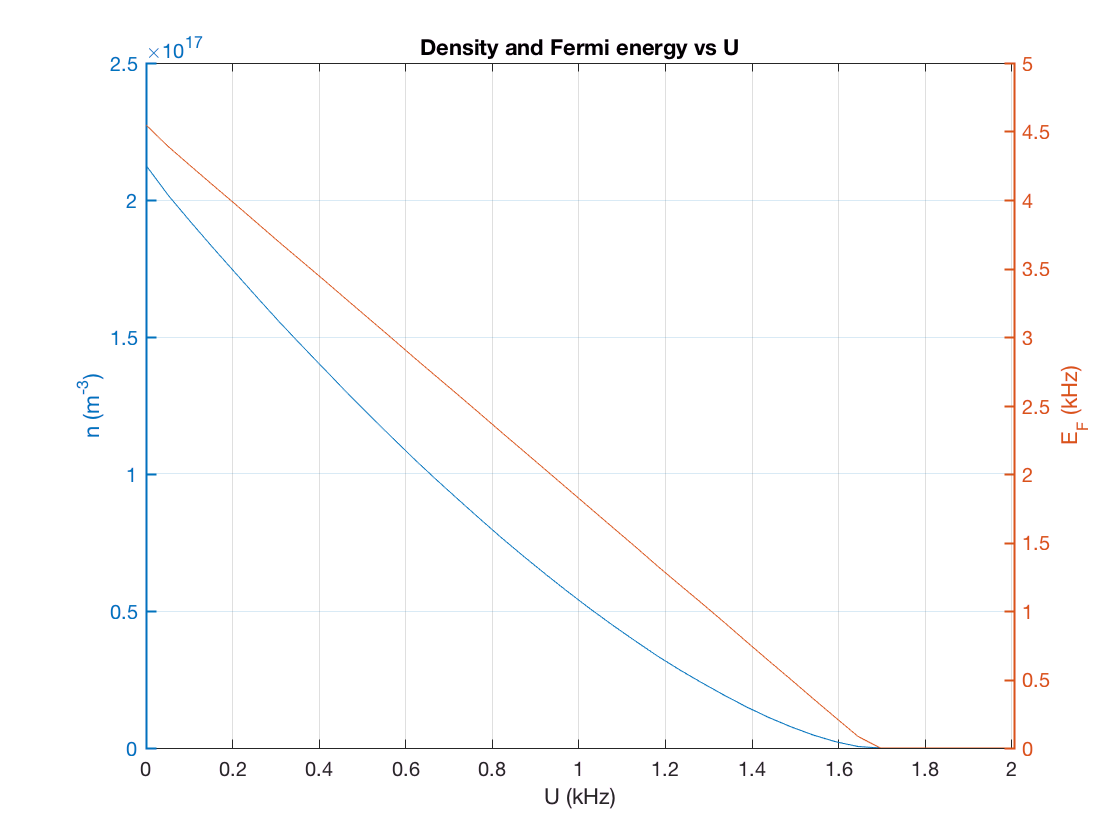

% Calculate n_U and EF_U and U_i by binning
total_bins = 40;
U_i = linspace(0,max(U_z),total_bins+1)'; % Note that size now is total_bins+1. This is neccesary for binning and will be removed later.
n_U = zeros(total_bins,1);
whichbin = discretize(U_z,U_i);
for i=1:total_bins
    binMembers = n_z(whichbin == i);
    n_U(i) = mean(binMembers);
end
U_i = U_i(1:end-1); % Fixing the extra
EF_U = uconst.hbar^2 / (2*uconst.massLi6) * (6*pi^2*n_U).^(2/3);
clearvars whichbin binMembers i

% Plot n_U and EF_U
fig1 = figure; ax1 = subplot(1,1,1); grid on;  title('Density and Fermi energy vs U'); xlabel('U (kHz)'); xlim([U_i(1),U_i(end)]/(uconst.h*1e3)); 
yyaxis left
plot(U_i/(uconst.h*1e3),n_U);  ylabel('n (m^{-3})');
yyaxis right
plot(U_i/(uconst.h*1e3),EF_U/(uconst.h*1e3));  ylabel('E_F (kHz)');

clearvars fig1 ax1

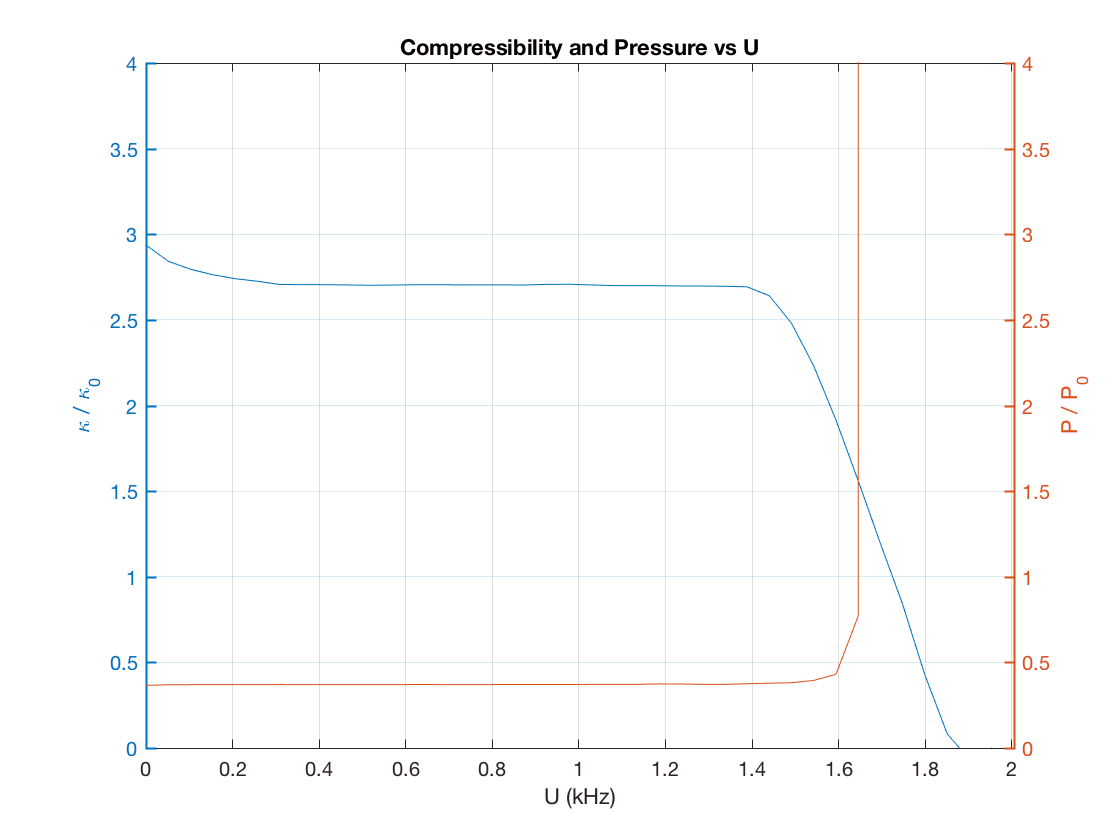

% Calculate P/P0 and k/k0
P_U = zeros(total_bins-1,1);
k_U = zeros(total_bins-1,1);

for i = 1:total_bins-1, P_U(i) = trapz(U_i(i:end),n_U(i:end)); end
P_U = P_U ./ (2/5*n_U(1:end-1).*EF_U(1:end-1)) ;

k_U = - diff(EF_U) / (U_i(2)-U_i(1)); 

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale');
for i = 1:length(k_U)
    t = 5;
    p = polyfit(U_i(max(1,i-t):min(length(U_i),i+t)), EF_U(max(1,i-t):min(length(U_i),i+t)), 2);
%    k_U(i) =  - (polyval(p,U_i(i+1),[],mu) - polyval(p,U_i(i),[],mu)) / ((U_i(i+1)-U_i(i)));
     k_U(i) =  - polyval(polyder(p),U_i(i));
end

% Plot P_U and k_U
fig1 = figure; ax1 = subplot(1,1,1); grid on;  title('Compressibility and Pressure vs U');  xlabel('U (kHz)'); xlim([U_i(1),U_i(end)]/(uconst.h*1e3));
yyaxis left
plot(U_i(1:end-1)/(uconst.h*1e3),k_U); ylim([0 4]);  ylabel('\kappa / \kappa_0');
yyaxis right
plot(U_i(1:end-1)/(uconst.h*1e3),P_U); ylim([0 4]); ylabel('P / P_0');

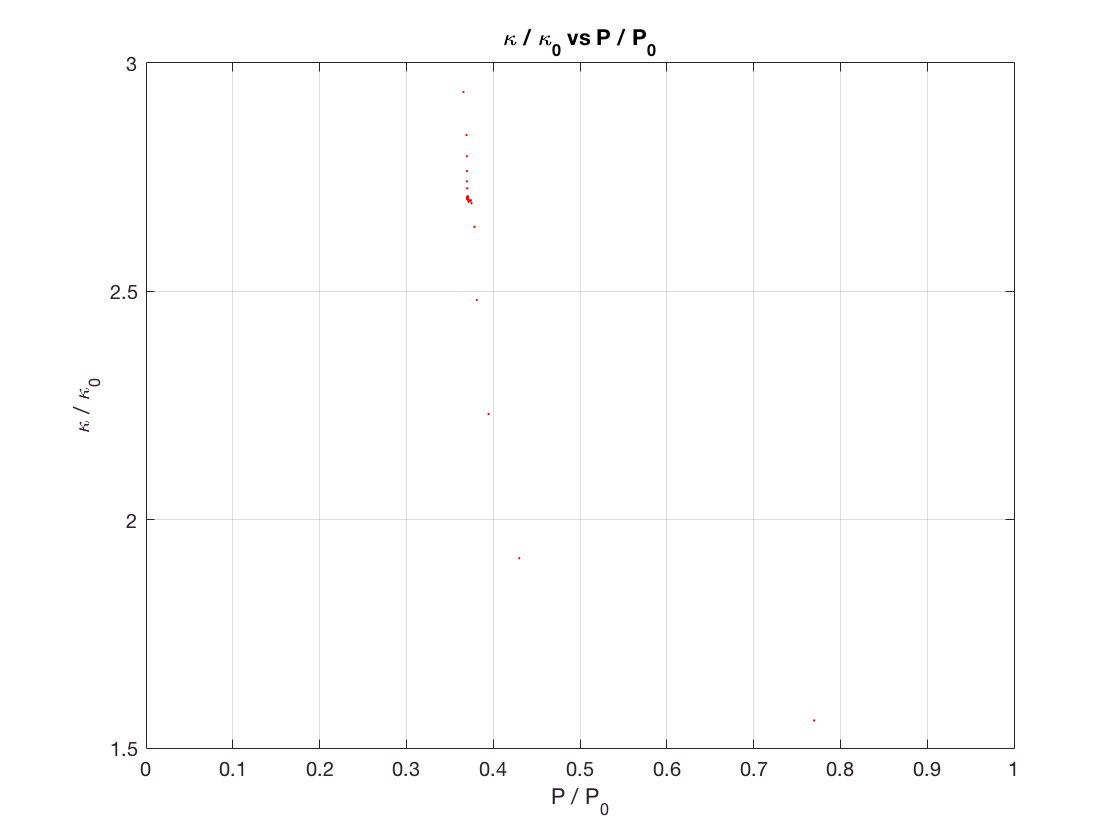

clearvars fig1 ax1

% Plot k_U vs P_U
figure; 
plot(P_U,k_U,'r.'); xlim([0 1]);
grid on; title('\kappa / \kappa_0 vs P / P_0'); xlabel('P / P_0'); ylabel('\kappa / \kappa_0');

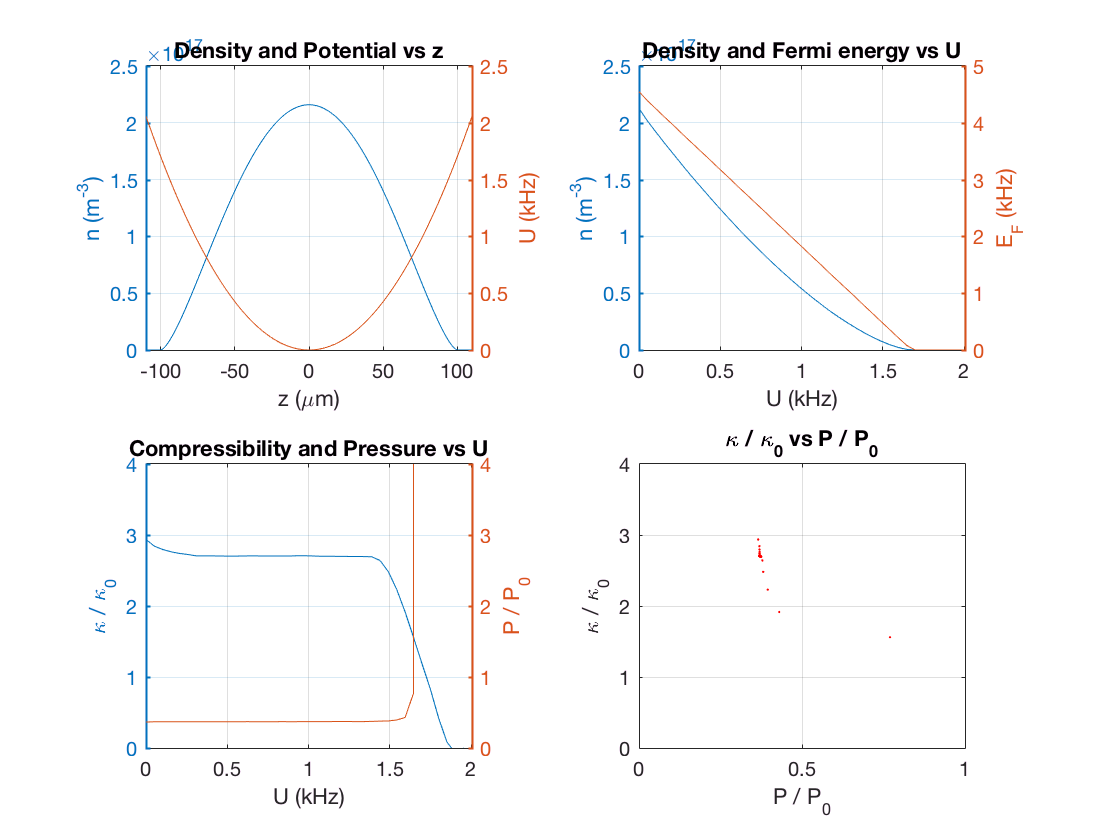

% Create final plot and save data
save testfakedata.mat econst uconst z_i n_z U_z U_i n_U EF_U P_U k_U total_bins;

figure;
subplot(2,2,1);
grid on; title('Density and Potential vs z');  xlim([z_i(1),z_i(end)]*1e6); xlabel('z (\mum)');
yyaxis left
plot(z_i*1e6,n_z);  ylabel('n (m^{-3})');
yyaxis right
plot(z_i*1e6,U_z/(uconst.h*1e3)); ylabel('U (kHz)');

subplot(2,2,2);
grid on;  title('Density and Fermi energy vs U'); xlabel('U (kHz)'); xlim([U_i(1),U_i(end)]/(uconst.h*1e3)); 
yyaxis left
plot(U_i/(uconst.h*1e3),n_U);  ylabel('n (m^{-3})');
yyaxis right
plot(U_i/(uconst.h*1e3),EF_U/(uconst.h*1e3));  ylabel('E_F (kHz)');

subplot(2,2,3);
grid on;  title('Compressibility and Pressure vs U');  xlabel('U (kHz)'); xlim([U_i(1),U_i(end)]/(uconst.h*1e3));
yyaxis left
plot(U_i(1:end-1)/(uconst.h*1e3),k_U); ylim([0 4]);  ylabel('\kappa / \kappa_0');
yyaxis right
plot(U_i(1:end-1)/(uconst.h*1e3),P_U); ylim([0 4]); ylabel('P / P_0');

subplot(2,2,4);
plot(P_U,k_U,'r.'); xlim([0 1]); ylim([0 4]);
title('\kappa / \kappa_0 vs P / P_0'); xlabel('P / P_0'); ylabel('\kappa / \kappa_0'); grid on;